# ENPM 667 Controls of Robotic Systems

## Info Section

% Author: Akshitha Pothamshetty
% Section: 0201

## Part D

% Choose M = 1000Kg, m 1 = m 2 = 100Kg, l 1 = 20m and l 2 = 10m. Check that
% the system is controllable and obtain an LQR controller. Simulate the resulting response to initial
% conditions when the controller is applied to the linearized system and also to the original nonlinear
% system. Adjust the parameters of the LQR cost until you obtain a suitable response. Use Lyapunov’s
% indirect method to certify stability (locally or globally) of the closed-loop system.


% Setting Given Variables

m1 = 100;
m2 = 100;
M = 1000;
l1 = 20;
l2 = 10;
g = 9.81;

% Check if System is controllable?

A = [0 1            0           0       0            0;
     0 0        -m1*g/M         0   -m2*g/M          0;
     0 0            0           1       0            0;
     0 0    -g*(M+m1)/(M*l1)    0 -(m2*g)/(M*l1)     0;
     0 0            0           0       0            1;
     0 0    -(m1*g)/(M*l2)      0 -(g*(M+m2))/(M*l2) 0];
 
% disp(A);
 
B= [  0  ; 
     1/M ;
      0  ; 
    1/(M*l1);
      0  ;
    1/(M*l2)];

disp(rank(ctrb(A,B))); % Rank = 6(Full Rank) Hence Controlable.

     6




% Obtaining an LQR Controller

C=[1 0 0 0 0 0;
   0 1 0 0 0 0;
   0 0 1 0 0 0;
   0 0 0 0 1 0];

D = [0];

% Selecting appropriate Q and R Values
Q = [1 0 0 0 0 0;
     0 1 0 0 0 0;
     0 0 10 0 0 0;
     0 0 0 1000 0 0;
     0 0 0 0 200 0;
     0 0 0 0 0 2000];
 
R = 0.0001;

% Gain Matrix
K = lqr(A, B, Q, R);
% disp(K);

disp(eig(A - B*K)); % Lyapunov Indirect Method: All eigen Values are on the left hand side, so system is stable.

  -0.2428 + 1.0205i
  -0.2428 - 1.0205i
  -0.2051 + 0.2028i
  -0.2051 - 0.2028i
  -0.0548 + 0.7229i
  -0.0548 - 0.7229i



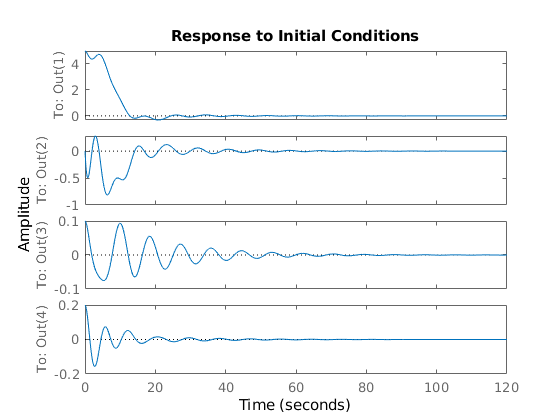

sys = ss(A-B*K, B, C, D); % Create a state-space system.

intialState = [5;
               0;
               0.1;
               0;
               0.2;
               0];
           
initial(sys, intialState)

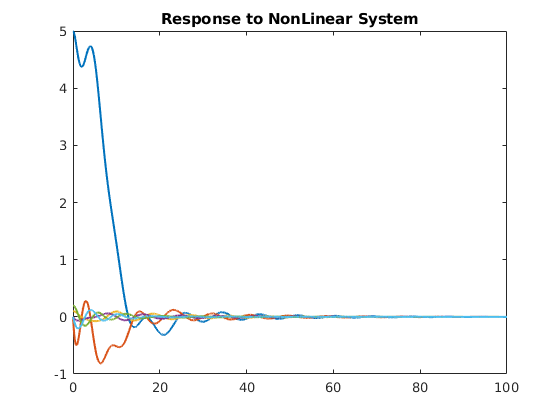



% Response to Non-Linear System

t = 0:0.01:100; % TimeSteps
[t,x]=ode45(@State,t,intialState);
plot(t,x,'linewidth',1.5);
title('Response to NonLinear System');

## Part E

A = [0 1            0           0       0            0;
     0 0        -m1*g/M         0   -m2*g/M          0;
     0 0            0           1       0            0;
     0 0    -g*(M+m1)/(M*l1)    0 -(m2*g)/(M*l1)     0;
     0 0            0           0       0            1;
     0 0    -(m1*g)/(M*l2)      0 -(g*(M+m2))/(M*l2) 0];
 
% Case I: Output Vector : x(t)
C = [1 0 0 0 0 0];
disp(rank(obsv(A,C))); % Observable as Rank = 6(Full Rank)

     6




% Case II: Output Vector : (θ 1 (t), θ 2 (t))
C = [0 0 0 1 0 0;
     0 0 0 0 1 0];
disp(rank(obsv(A,C)));% Not Observable as Rank = 4 < 6

     4




% Case III: Output Vector : (x(t), θ 2 (t))
C = [1 0 0 0 0 0;
     0 0 0 0 1 0];
disp(rank(obsv(A,C)));% Observable as Rank = 6(Full Rank)

     6




% Case IV: Output Vector : (x(t), θ 1 (t), θ 2 (t))
C = [1 0 0 0 0 0;
     0 0 1 0 0 0;
     0 0 0 0 0 1];
disp(rank(obsv(A,C)));% Observable as Rank = 6(Full Rank)

     6



## Part F

% Obtain your "best" Luenberger observer for each one of the output vectors for which the system is
% observable and simulate its response to initial conditions and unit step input. The simulation should
% be done for the observer applied to both the linearized system and the original nonlinear system.

## Luenberger Observer for Output x(t)

% Setting Given Variables
m1 = 100;
m2 = 100;
M = 1000;
l1 = 20;
l2 = 10;
g = 9.81;

% Check if System is controllable?

A = [0 1            0       0       0       0;
     0 0        -m1*g/M     0   -m2*g/M     0;
     0 0            0       1       0       0;
     0 0 -g*(M+m1)/(M*l1)   0 -(m2*g)/(M*l1) 0;
     0 0            0       0       0        1;
     0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];
 
% disp(A);
 
B= [ 0; 1/M ;0; 1/(M*l1) ;0 ;1/(M*l2)];

% disp(rank(ctrb(A,B))); % Rank = 6(Full Rank) Hence Controlable.

% Obtaining an LQR Controller

C=[1 0 0 0 0 0];

D = [0];

% Selecting appropriate Q and R Values
Q = [1 0 0 0 0 0;
     0 1 0 0 0 0;
     0 0 10 0 0 0;
     0 0 0 1000 0 0;
     0 0 0 0 200 0;
     0 0 0 0 0 2000];
 
R = 0.0001;

% Gain Matrix
K = lqr(A, B, Q, R);
% disp(K);

p = [-2 -3 -4 -5 -6 -7];
L = place(A.', C.', p);
L = L.';
disp(L);

   1.0e+04 *

    0.0027
    0.0293
   -1.4999
   -0.5404
    1.3346
    0.0686



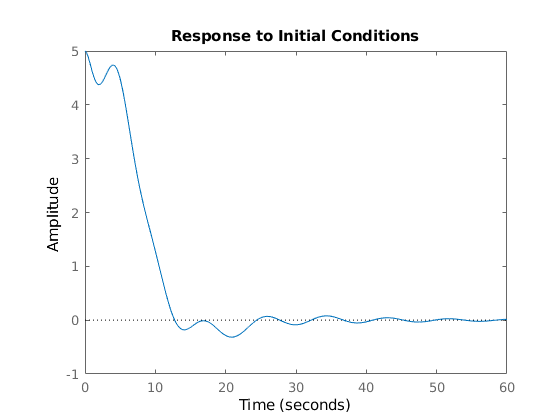


eig(A-L*C);

Ac = [(A-B*K) (B*K); zeros(size(A)) (A-L*C)];
Bc=[ B ;zeros(size(B))];
Cc= [C zeros(size(C))];
Dc=[0];

sys = ss(Ac,Bc,Cc,Dc);

initialState = [ 5 ; 0 ; 0.1 ; 0 ;0.2 ; 0 ; 0 ; 0 ; 0 ; 0 ; 0 ; 0];

initial(sys, initialState);

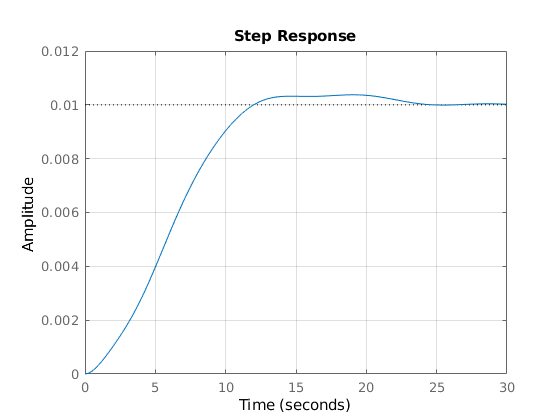

step(sys);
grid;

## Luenberger Observer for Output [x(t), theta2(t)]

C=[1 0 0 0 0 0 ; 0 0 0 0 1 0];

p = [-2 -3 -4 -5 -6 -7];
L = place(A.', C.', p);
L = L.';
disp(L);

  Column 1

   17.2418
  103.7782
 -256.4987
 -174.6426
    0.6195
    7.4369

  Column 2

   -1.9388
  -26.1469
  101.6392
  110.3637
    9.7582
   20.1529



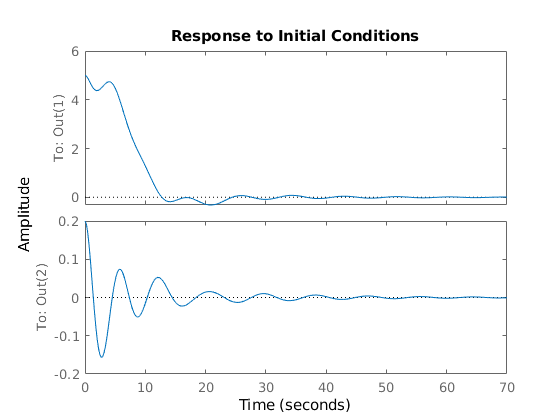


eig(A-L*C);

Ac = [(A-B*K) (B*K); zeros(size(A)) (A-L*C)];
Bc=[ B ;zeros(size(B))];
Cc= [C zeros(size(C))];
Dc=[0];

sys = ss(Ac,Bc,Cc,Dc);

initialState = [ 5 ; 0 ; 0.1 ; 0 ;0.2 ; 0 ; 0 ; 0 ; 0 ; 0 ; 0 ; 0];

initial(sys, initialState);

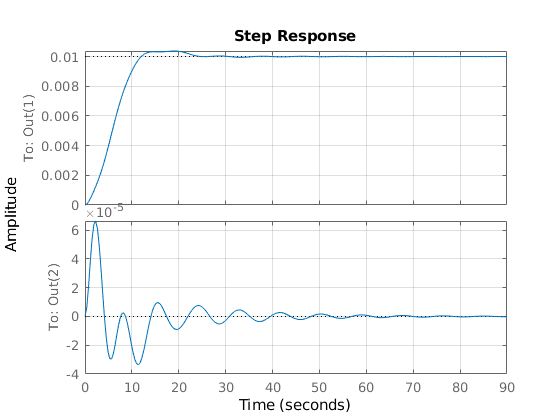

step(sys);
grid;

## Luenberger Observer for Output [x(t) theta1(t) theta2(t)]

C=[1 0 0 0 0 0 ; 0 0 1 0 0 0; 0 0 0 0 1 0];

p = [-2 -3 -4 -5 -6 -7];
L = place(A.', C.', p);
L = L.';
disp(L);

  Column 1

   10.4331
   26.3638
   -0.8468
   -4.6605
    0.0000
    0.0000

  Column 2

   -0.8011
   -5.3594
   11.5669
   32.0963
   -0.0000
   -0.0981

  Column 3

    0.0000
   -0.9810
   -0.0000
   -0.0492
    5.0000
    4.9209



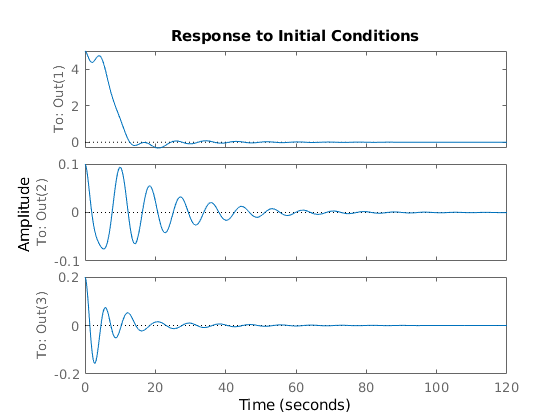


eig(A-L*C);

Ac = [(A-B*K) (B*K); zeros(size(A)) (A-L*C)];
Bc=[ B ;zeros(size(B))];
Cc= [C zeros(size(C))];
Dc=[0];

sys = ss(Ac,Bc,Cc,Dc);

initialState = [ 5 ; 0 ; 0.1 ; 0 ;0.2 ; 0 ; 0 ; 0 ; 0 ; 0 ; 0 ; 0];

initial(sys, initialState);

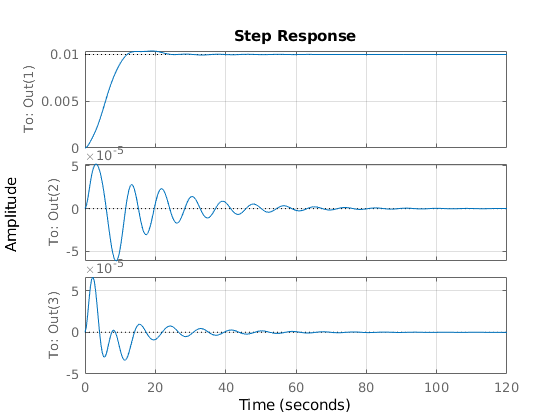

step(sys);
grid;

## Part G

% Design an output feedback controller for your choice of the "smallest" output vector. Use the LQG
% method and apply the resulting output feedback controller to the original nonlinear system. Obtain
% your best design and illustrate its performance in simulation. How would you reconfigure your con-
% troller to asymptotically track a constant reference on x ? Will your design reject constant force
% disturbances applied on the cart ?


% Setting Given Variables
m1 = 100;
m2 = 100;
M = 1000;
l1 = 20;
l2 = 10;
g = 9.81;

% Setting Parameters for LQE & LQR
disturbance = 0.1 * eye(1);
noise = 1;
sensors = [1];
known = [1];
states = {'x','x_dot','theta1','theta1_dot','theta2','theta2_dot','e_1','e_2','e_3','e_4','e_5','e_6'};
inputs = {'F'};
outputs = {'x'};
initialState = [ 5 ; 0 ; 0.1 ; 0 ;0.2 ; 0 ; 0 ; 0 ; 0 ; 0 ; 0 ; 0];

% Check if System is controllable?

A = [0 1            0       0       0       0;
     0 0        -m1*g/M     0   -m2*g/M     0;
     0 0            0       1       0       0;
     0 0 -g*(M+m1)/(M*l1)   0 -(m2*g)/(M*l1) 0;
     0 0            0       0       0        1;
     0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];
 
% disp(A);
 
B= [ 0; 1/M ;0; 1/(M*l1) ;0 ;1/(M*l2)];

% disp(rank(ctrb(A,B))); % Rank = 6(Full Rank) Hence Controlable.

% Obtaining an LQR Controller

C=[1 0 0 0 0 0];

D = [0];

% Selecting appropriate Q and R Values
Q = [1 0 0 0 0 0;
     0 1 0 0 0 0;
     0 0 10 0 0 0;
     0 0 0 1000 0 0;
     0 0 0 0 200 0;
     0 0 0 0 0 2000];
 
R = 0.0001;

% Gain Matrix
K = lqr(A, B, Q, R);
% disp(K);

% LQE Design
system = ss(A,[B B],C,[zeros(1,1) zeros(1,1)]);
[~,L,~] = kalman(system,disturbance,noise,[],sensors,known); % filter gain L
disp(L);

    0.0230
    0.0003
    0.0000
    0.0000
    0.0000
    0.0000



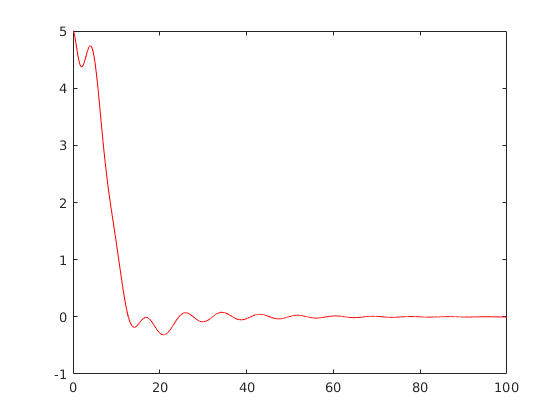


% LQR Design
Ac = [A-B*K B*K;zeros(size(A)) A-L*C];
Bc = zeros(12,1);
Cc = [C zeros(size(C))];
LQG = ss(Ac,Bc,Cc,D, 'statename',states,'inputname',inputs,'outputname',outputs);    

time = 0:0.01:100; % Timesteps
Force = zeros(size(time)); % External Force

% Simulate Time Response
[Y,~,X] = lsim(LQG,Force,time,initialState);
figure
plot(time,Y(:,1),'r');

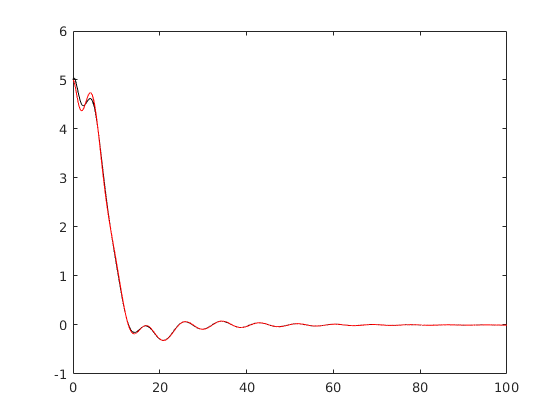


u = zeros(size(time)); % Input

for i = 1:size(X,1)
   u(i) = K * (X(i,1:6))';
end

Xhat = X(:,1) - X(:,6); % Error Tracking
figure;
plot(time,Xhat, 'k'), hold on, plot(time,X(:,1),'r');

function xDot = State(t,x)


% Setting Given Variables

m1 = 100;
m2 = 100;
M = 1000;
l1 = 20;
l2 = 10;
g = 9.81;


A = [0 1            0       0       0       0;
     0 0        -m1*g/M     0   -m2*g/M     0;
     0 0            0       1       0       0;
     0 0 -g*(M+m1)/(M*l1)   0 -(m2*g)/(M*l1) 0;
     0 0            0       0       0        1;
     0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];
 
% disp(A);
 
B= [ 0; 1/M ;0; 1/(M*l1) ;0 ;1/(M*l2)];

% Selecting appropriate Q and R Values
Q = [1 0 0 0 0 0;
     0 1 0 0 0 0;
     0 0 10 0 0 0;
     0 0 0 1000 0 0;
     0 0 0 0 200 0;
     0 0 0 0 0 2000];
 
R = 0.0001;

K = lqr(A, B, Q, R);
u = -K*x;

xDot = zeros(6,1);

xDot(1)= x(2);
xDot(2)= -((-u) + m1*l1*x(4)^2*sin(x(3)) + m1*g*sin(x(3))*cos(x(3))+ m2*l2*x(6)^2*sin(x(5))+m2*g*sin(x(5))*cos(x(5)))/(M+m1*sin(x(3)^2)+ m2*sin(x(5)^2));
xDot(3)= x(4);
xDot(4)= -((-u) +(M+m1)*g*sin(x(3)) + m1*l1*x(4)^2*sin(x(3))*cos(x(3)) + m2*l2*x(6)^2*sin(x(5))*cos(x(3)) + m2*g*sin(x(5))*cos(x(3)- x(5)))/(( M+ m1*sin(x(3)^2)+ m2*sin(x(5)^2))*l1);
xDot(5)= x(6);
xDot(6)= -((-u) + m1*l1*x(4)^2*sin(x(3))*cos(x(5)) +m1*g*sin(x(3))*cos(x(3)-x(5)) + (M+m1)*g*sin(x(5))+m2*l2*x(6)^2*sin(x(5))*cos(x(5)))/(( M+m1*sin(x(3)^2)+ m2*sin(x(5)^2))*l2);
end